# Lab 4: Time-frequency representations and Haar wavelets

## Short term Fourier transforms

### Question 4.1

load data2_1
fs=15.5;
% finish it



n = length(x); %Number of samples in data

% % w = floor(n/2);  %Window size for short term fourier transform
% % overlap = floor(w/2); %Overlap between consecutive windows
% w = 1024;
% overlap = 960;
% 
% hw = hamming(w);

% % Compute the STFT using a Hamming window
% [S, F, T] = spectrogram(x, hamming(w), overlap, w, fs, 'yaxis', 'xaxis');
% SdB = 10*log10(abs(S)); %Convert to dB
% T = T/60; %make the time in minutes
% F = F;
% 
% % Plot the spectrogram
% figure('Name', 'Spectrogram using Short-Time Fourier Transform with Hamming Window');
% imagesc(T, F, SdB); 
% c = colorbar;
% c.Label.String = 'Power/frequency (dB/Hz)';
% axis xy;  % Flip the y-axis to have low frequencies at the bottom
% xlabel('Time (min)');
% ylabel('Frequency (Hz)');
% title('Spectrogram using Short-Time Fourier Transform with Hamming Window');

There is a much easier way to do then this... Let's try again. --> does NOT work either way.

Make it easier and more correct:

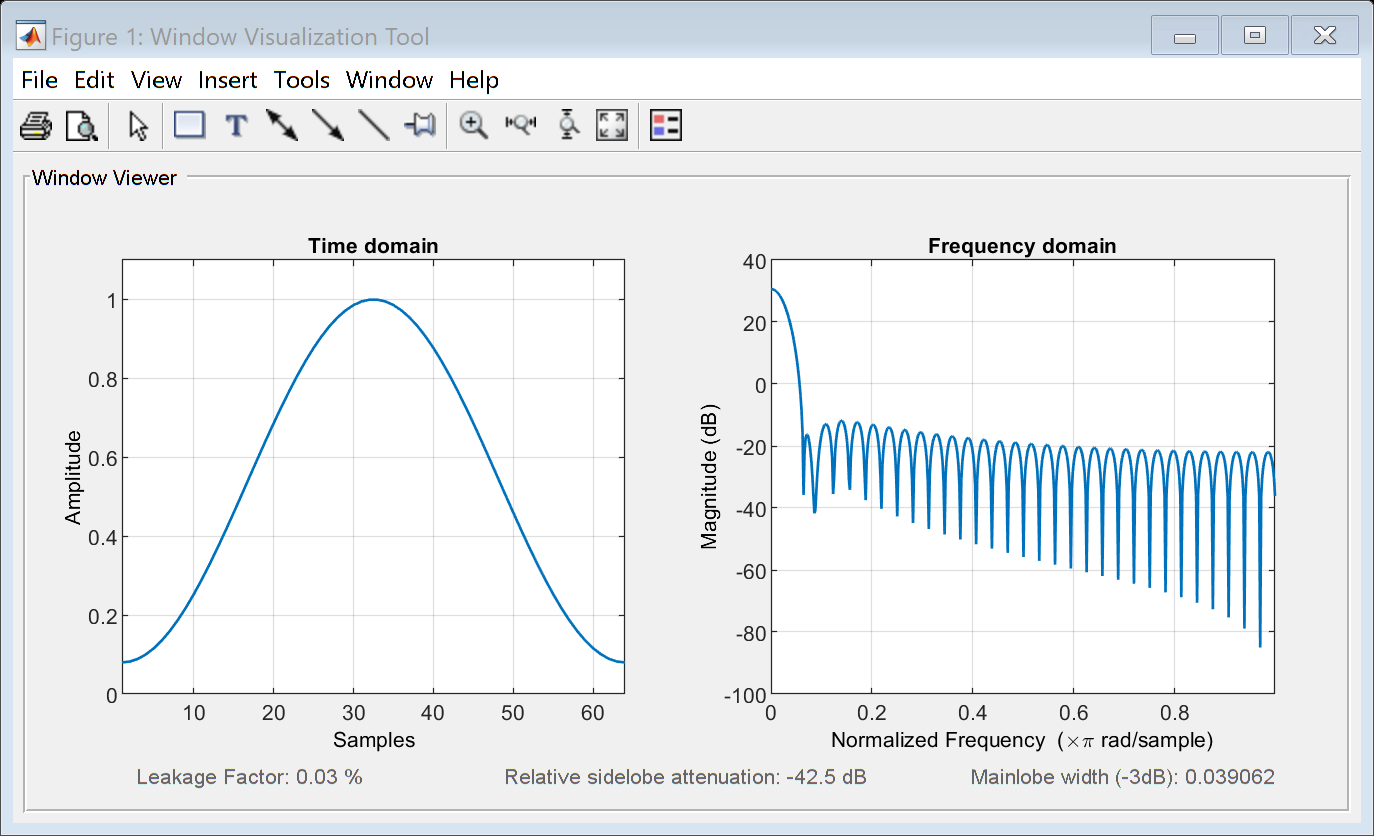

H = hamming(64);
wvtool(hamming(64));     %visualizing a 64-point hamming window.

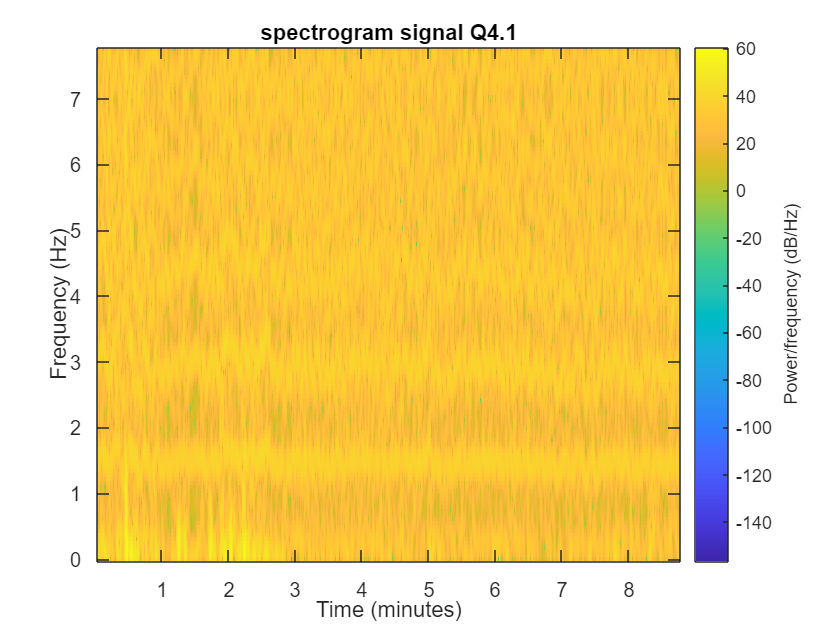

figure
spectrogram(x,H,60,[],fs,'yaxis')
title("spectrogram signal Q4.1")

### Question 4.2 and 4.3

figure
s1=subplot(2,1,1)

s1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


t = (0:n-1) * (1/fs);
tm = t/60 % make it in minutes

tm =          0    0.0011    0.0022    0.0032    0.0043    0.0054    0.0065    0.0075    0.0086    0.0097    0.0108    0.0118    0.0129    0.0140    0.0151    0.0161    0.0172    0.0183    0.0194    0.0204    0.0215    0.0226    0.0237    0.0247    0.0258    0.0269    0.0280    0.0290    0.0301    0.0312    0.0323    0.0333    0.0344    0.0355    0.0366    0.0376    0.0387    0.0398    0.0409    0.0419    0.0430    0.0441    0.0452    0.0462    0.0473    0.0484    0.0495    0.0505    0.0516    0.0527


plot(tm,x)
%xlim()
title("signal x in time domain")
xlabel("time (min.)")

% todo time signal
s2=subplot(2,1,2)

s2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


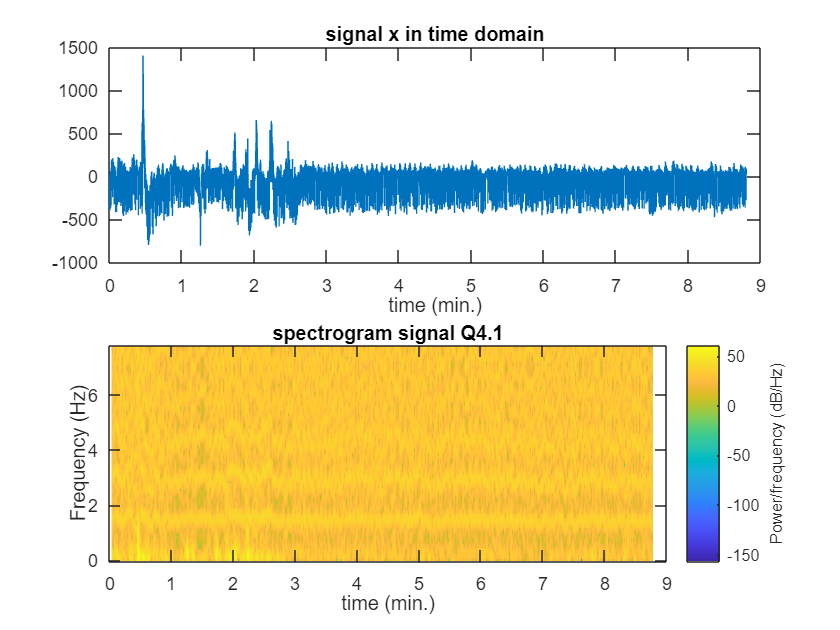

spectrogram(x,H,60,[],fs,'yaxis')
title("spectrogram signal Q4.1")
xlabel("time (min.)")

% todo spectrogram
linkaxes([s1, s2], 'x');

**QUESTION:**

**Can you find out what the dominant frequencies are and at what time-instances there is a problem  with baseline wander?**

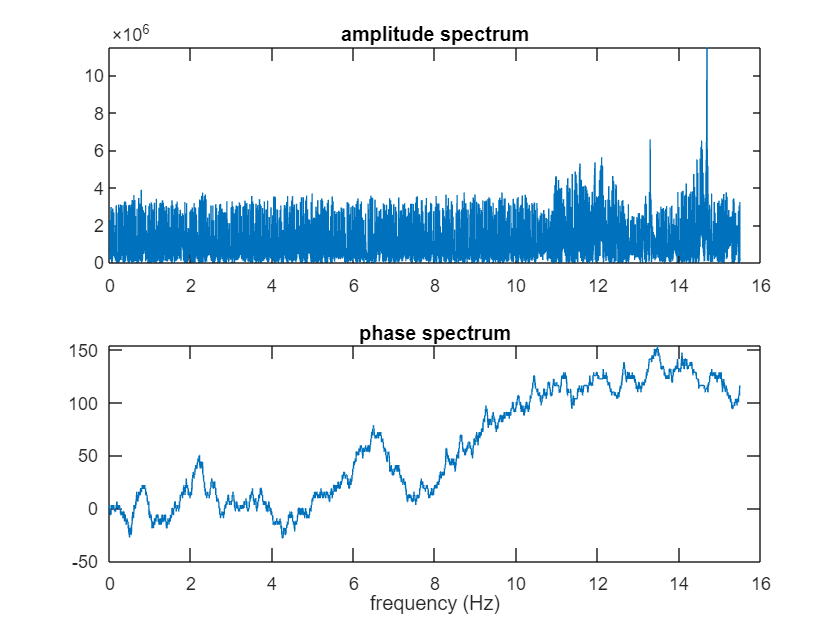

ans = 1.0e+07 *

    0.0246    0.0229    0.0229    0.0319    0.0352    0.0754    0.0754    0.2261    0.0614    0.0180    0.0270    0.0311    0.0344    0.0393    0.0467    0.0475    0.0254    0.0877    0.0918    0.0795    0.2966    0.0352    0.0393    0.0336    0.0311    0.0377    0.0311    0.0106    0.0393    0.0483    0.0033    0.2736    0.0090    0.0049    0.0016    0.0090    0.0197    0.0369    0.0213    0.0352    0.0705    0.0762    0.2892    0.0573    0.0319    0.0459    0.0418    0.0377    0.0410    0.0500


%do as it was done in previous labs:
Sx = fft(x);
plotfft(Sx, fs)

**A: This definitely does notgive us good information. **

% the positions of the dominant frequencies can be found the same way as it
% was donein lab 3
[values,idx] = sort(abs(Sx),'descend')

values = 1.0e+04 *

    6.9710    6.9710    6.9398    6.9398    6.9234    6.9234    6.8956    6.8956    6.7937    6.7937    6.7770    6.7770    6.3067    6.3067    5.8717    5.8717    5.8712    5.8712    5.7707    5.7707    5.6132    5.6132    5.5218    5.5218    5.4086    5.4086    5.2531    5.2531    5.2177    5.1244    5.1244    4.9511    4.9511    4.8541    4.8541    4.7466    4.7466    4.7055    4.7055    4.6821    4.6821    4.6770    4.6770    4.5363    4.5363    4.5355    4.5355    4.5159    4.5159    4.5069


idx =           51        8143          39        8155          40        8154          85        8109          52        8142          86        8108          50        8144         100        8094          63        8131          46        8148          41        8153          45        8149          53        8141          62        8132           1          16        8178          28        8166          20        8174          75        8119          71        8123          35        8159          15        8179         130        8064          57        8137         143        8051        1565


f = (0:length(x)-1)*fs/length(x);

fd=f(idx(:,1:2))

fd =     0.0946   15.4054


**A: The dominant frequencies have a magnitude of 10^4*6.9710. with frequencies: 0.0946Hz and 15.4054Hz**

**Q: Can you, using this data and its spectrogram, discover which frequencies are involved with the QRS  complex?**

-> What is a qrs complex?

The QRS complex is the combination of three of the graphical deflections seen on a typical electrocardiogram. It is usually the central and most visually obvious part of the tracing. It corresponds to the depolarization of the right and left ventricles of the heart and contraction of the large ventricular muscles.

A combination of the Q wave, R wave and S wave, the “QRS complex” represents ventricular depolarization. This term can be confusing, as not all ECG leads contain all three of these waves; yet a “QRS complex” is said to be present regardless.

**A: ??????**

## Haar wavelets on signals

### Question 4.4

Implement the Haar wavelet transform in the function dwlt_haar. Note that for other wavelets, this will not work as easily, hence, the explicit mention that it is for the haar wavelet.

This function should look something like this (Remember to save it in a seperate .m file)

and be in the same folder as this Matlab live script file. Then complete this code

x=[1 4 2 3 1 0 0 2]; %signal
c=[1, 1]/sqrt(2); % low-pass
d=[1, -1]/sqrt(2); % high-pass
[a,b] = dwlt_haar(x,c,d);

a=
    3.5355    3.5355    0.7071    1.4142

b=
    2.1213    0.7071   -0.7071    1.4142



signal_energy =x*x'; %signal energy
coefficients_energy = sum(a.^2) + sum(b.^2);%coefficients energy
signal_energy

signal_energy = 35

coefficients_energy

coefficients_energy = 35.0000

Also test your code witht he examples from the lectures. you may assume your signal is of even length.

### Question 4.5

Write the idwlt_haar function in this structure (Remember to save it in a seperate .m file)

Test it not just on the signal provided, but also on the ones from the lecture slides. Obviously, each signal you feed through dwlt_haar and idwlt_haar consecutively should be perfect reconstructed.

Some more test cases with signal s, approximation coefficients a and detail coefficients b to help you

s=[-4    -9    -8     6     4    -4     9    -9    -1    -2     5     6    -6     0    -1     3]

a=[-9.1924   -1.4142         0         0   -2.1213    7.7782   -4.2426    1.4142]

b=[-3.5355    9.8995   -5.6569  -12.7279   -0.7071    0.7071    4.2426    2.8284]

s=[4     5    -4     4     3    -7    -8     0     9    -3     2    -6     5    -5     0     4]

a=[6.3640         0   -2.8284   -5.6569    4.2426   -2.8284         0    2.8284]

b=[0.7071    5.6569   -7.0711    5.6569   -8.4853   -5.6569   -7.0711    2.8284]

s=[8     9     1    -7    -7    -5     7    -5     6    -5     9    -3    -6    -5     2    -1]

a=[12.0208   -4.2426   -8.4853    1.4142    0.7071    4.2426   -7.7782    0.7071]

b=[0.7071   -5.6569    1.4142   -8.4853   -7.7782   -8.4853    0.7071   -2.1213]

You can use the norm function to spot differences

 %try using the inverse Haar to see if the function works porperly
% c=[1, 1]/sqrt(2); % low-pass
% d=[1, -1]/sqrt(2); % high-pass
a=[-9.1924   -1.4142         0         0   -2.1213    7.7782   -4.2426    1.4142]

a =    -9.1924   -1.4142         0         0   -2.1213    7.7782   -4.2426    1.4142


b=[-3.5355    9.8995   -5.6569  -12.7279   -0.7071    0.7071    4.2426    2.8284]

b =    -3.5355    9.8995   -5.6569  -12.7279   -0.7071    0.7071    4.2426    2.8284


s = idwlt_haar(a,b,c,d);

Signal s=
   -4.0000   -9.0000   -8.0000    6.0000    4.0000   -4.0000    9.0000   -9.0000   -1.0000   -2.0000    5.0000    6.0000   -5.9999         0   -1.0000    3.0000



%ORDER IS DIFFERENT BUT IT IS NORMAL!

x =[-4    -9    -8     6     4    -4     9    -9    -1    -2     5     6    -6     0    -1     3]%signal we are supposed to get

x =     -4    -9    -8     6     4    -4     9    -9    -1    -2     5     6    -6     0    -1     3


check = norm(x-s);

check

check = 9.7269e-05

### Question 4.6

Finish the wldecom_haar function (Remember to save it in a seperate .m file)

And test it properly

s = [1 4 2 3 1 0 0 2]

s =      1     4     2     3     1     0     0     2


c=[1/sqrt(2) 1/sqrt(2)];     % low-pass
d=[1/sqrt(2) -1/sqrt(2)];    % high-pass


wldecom_haar(s,3,c,d)

ans =     4.5962   -2.4749         0    0.5000    2.1213    0.7071   -0.7071    1.4142


## Haar Wavelets on images

### Question 4.7

Implement a dwlt2_haar function starting with the structure

Probably it is wise to also call dwlt_haar from here (hint)

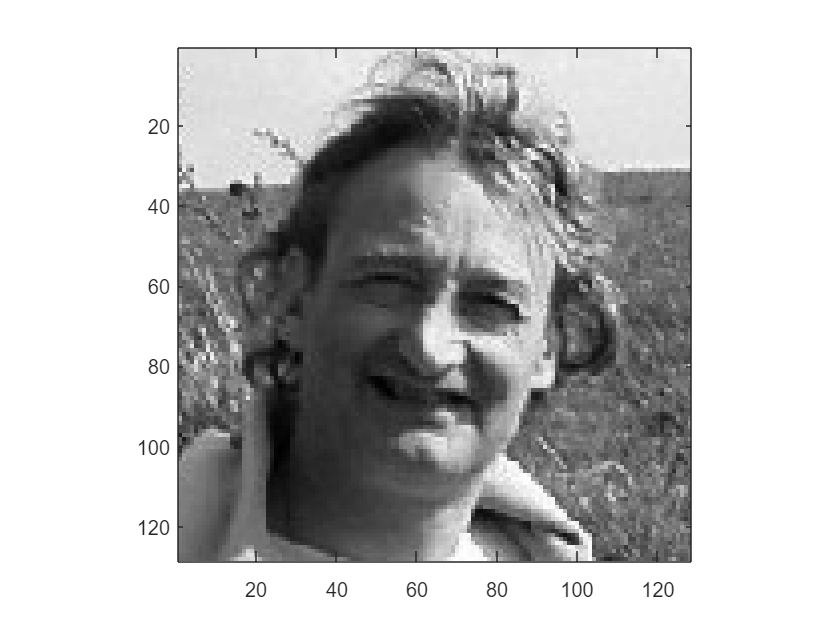

load ronald
figure
imagesc(ronald)
colormap gray
axis image


[B,H,V,D] = dwlt2_haar(ronald,c,d);

a=
  320.3194  315.3696  313.9554  313.9554  313.9554  311.1270  313.9554  314.6625  315.3696  318.1981  319.6123  323.1478  323.8549  322.4407  323.1478  325.2691  328.0975  318.9052  321.0265  325.2691  324.5620  323.1478  326.6833  323.8549  327.3904  328.0975  323.8549  313.9554  312.5412  337.2899  335.8757  301.9346  316.7838  265.8721  308.2986  333.0473  320.3194  326.6833  321.7336  329.5118  323.1478  325.9762  322.4407  316.7838  316.7838  321.0265  323.1478  327.3904  327.3904  328.8047  325.9762  323.1478  323.1478  324.5620  323.8549  326.6833  328.0975  329.5118  329.5118  332.3402  332.3402  337.9970  329.5118  329.5118

b=
   -2.1213    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.7071    0.0000   -0.0000   -0.0000    0.7071   -0.0000    0.0000    0.7071    1.4142    0.0000   -3.5355   -1.4142    1.4142   -2.1213    0.7071   -0.0000   -0.0000    0.7071    0.0000   -0.0000    5.6569    1.4142   17.6777    9.1924  -17.6777  -19.7990    4.2426    7.0711  

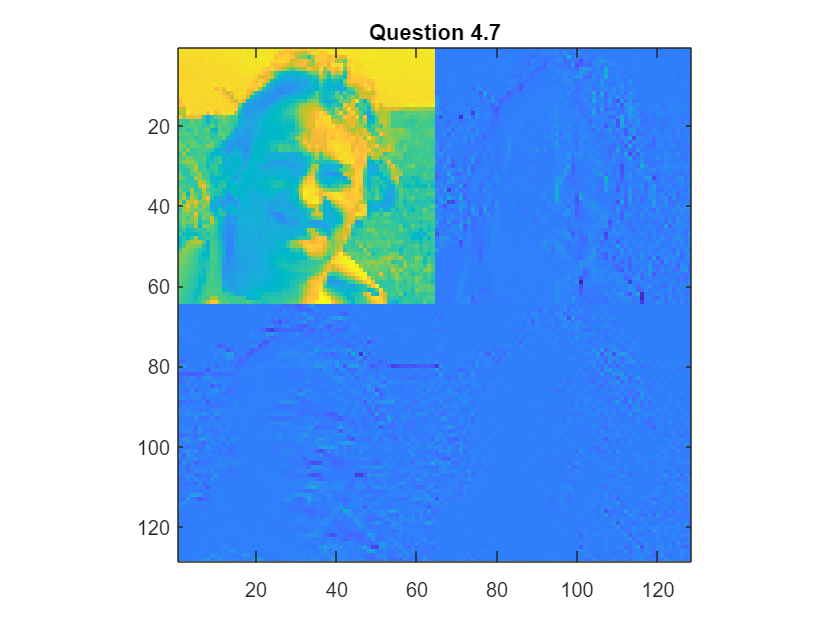

figure
imagesc([B V;H D])
axis image
title('Question 4.7')

### Question 4.8

Iterate the 2D composition using dwlt2_haar below

%q4.7 was 1-level haar transform --> repeat 3 times for 3-level
% B is what should be passed to go to higher levels

[B1,H1,V1,D1] = dwlt2_haar(ronald,c,d);

a=
  320.3194  315.3696  313.9554  313.9554  313.9554  311.1270  313.9554  314.6625  315.3696  318.1981  319.6123  323.1478  323.8549  322.4407  323.1478  325.2691  328.0975  318.9052  321.0265  325.2691  324.5620  323.1478  326.6833  323.8549  327.3904  328.0975  323.8549  313.9554  312.5412  337.2899  335.8757  301.9346  316.7838  265.8721  308.2986  333.0473  320.3194  326.6833  321.7336  329.5118  323.1478  325.9762  322.4407  316.7838  316.7838  321.0265  323.1478  327.3904  327.3904  328.8047  325.9762  323.1478  323.1478  324.5620  323.8549  326.6833  328.0975  329.5118  329.5118  332.3402  332.3402  337.9970  329.5118  329.5118

b=
   -2.1213    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.7071    0.0000   -0.0000   -0.0000    0.7071   -0.0000    0.0000    0.7071    1.4142    0.0000   -3.5355   -1.4142    1.4142   -2.1213    0.7071   -0.0000   -0.0000    0.7071    0.0000   -0.0000    5.6569    1.4142   17.6777    9.1924  -17.6777  -19.7990    4.2426    7.0711  

[B2,H2,V2,D2]=dwlt2_haar(B1,c,d); %go to level2 haar but with approximation coefs (B) from level 1

a=
  631.7999  627.9108  625.0824  627.9108  632.1535  644.8814  644.1743  645.5885  647.3563  649.4776  649.4776  653.7202  654.7809  595.7375  609.5260  593.2626  620.4862  625.7895  648.0634  647.0027  648.0634  640.2852  638.5174  653.7202  653.7202  647.7098  647.0027  649.8311  656.1951  662.9126  665.7410  662.5591

b=
   -5.3033   -0.0000   -2.8284    1.4142    1.4142    2.1213   -2.8284    2.8284   -8.1317    4.5962   -1.0607    1.7678    4.2426  -18.7383   -0.7071   -7.0711  -19.4454   26.1630    8.1317    3.5355    1.7678   -5.3033    3.5355    3.1820    0.3536   -1.4142    0.7071    2.1213    0.7071   -0.3536    3.8891   -0.7071

a=
  626.8502  627.9108  631.7999  627.2037  630.0321  637.8103  637.1032  635.3354  650.1847  656.9022  650.1847  649.1240  584.4238  574.8778  505.9349  449.0128  578.7669  603.5156  613.4151  642.7601  651.5989  646.6492  646.2956  655.1344  655.1344  651.2453  651.9525  647.7098  652.6596  649.1240  651.5989  662.5591

b=
   -3.8891    1.4142  

[B3,H3,V3,D3]=dwlt2_haar(B2, c,d); %go to level3 haar but with approximation coefs (B) from level 2

a=
   1.0e+03 *

    1.2572    1.2560    1.2724    1.2811    1.3020    1.3013    1.2049    1.0789    1.2143    1.2756    1.2933    1.2968    1.3039    1.2982    1.3104    1.3212

b=
   -1.4142   -0.8839   10.2530   -0.1768    4.4194    1.5910  -34.2947  -36.5928   15.0260   14.1421   -6.3640   12.0208   -4.9497   -0.7071    1.5910    3.8891

a=
   1.0e+03 *

    1.2429    1.2537    1.2636    1.2756    1.2979    1.2963    1.1932    0.9509    0.9613    1.0812    1.0775    1.3025    1.3000    1.2997    1.3023    1.3004

b=
    0.1768    8.1317    8.4853   -1.7678    1.4142  -13.6118    6.7175  -29.8753  196.9292  -37.4767  176.2464    8.1317    1.7678         0    1.2374    0.7071

a=
   1.0e+03 *

    1.2312    1.2443    1.2505    1.2680    1.2892    1.2390    1.0188    0.9180    1.0223    1.0994    1.1266    1.2664    1.2928    1.2977    1.2921    1.2931

b=
    6.1872    1.9445   -1.7678    0.5303    3.7123  -36.2392  -80.4334   54.6240   57.8060   87.1509   99.8788   21.5668    1.5910

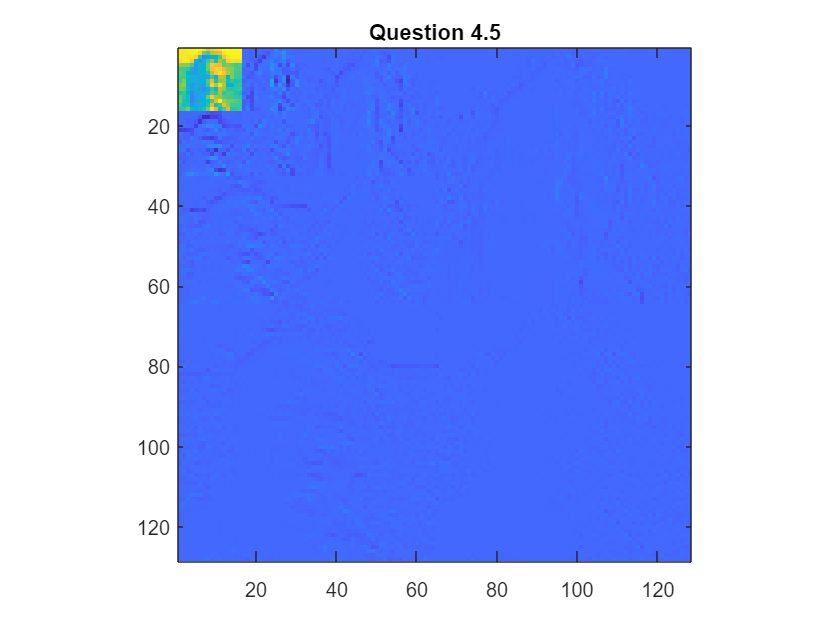

%combine back approximation and detail coefficients together
lvl3=[B3 V3;H3 D3];
lvl2=[lvl3 V2;H2 D2];
lvl1=[lvl2 V1;H1 D1];

figure
imagesc(lvl1)
axis image
title('Question 4.5')

## Haar wavelets and edge detection

### Question 4.9

From book : 

- Possibly the simplest thing we could do to detect edges in a digital image is to compute  the HWT, convert the values in the blur block Β to zero, and then apply the inverse  HWT.

- It is natural to assume that not every element in the detail matrices V, H, and V  constitute an edge in the original image. We can improve our edge detector by  keeping only those detail elements that do indeed correspond to edge pixels. The  mathematical procedure for selecting only particular elements from a set of numbers  is called thresholding.

- To apply a threshold to the elements of our transform matrix C, we simply choose a  value τ > 0 and create a new matrix C whose entries are Cij if tau < 0, 0 otherwise. 

- No proven way to choose tau --> Trial and error OR use of statistics

- To automate the process, we use an iterative method for determining τ. The process creates a series of thresholds τι , τ2 , • • • and  stops only when the difference ]r, l + i — r„ | is smaller than some prescribed a > 0:

1. Pick a tolerance a > 0 that will determine the stopping criteria for the process.  

2. Set τ ι to be the average of the largest and smallest values in S.  

3. Divide the values of S into two sets Si and S2 . The values in Si are all smaller  than τ and the values in S2 are greater than or equal to j\ . 

 4. Compute the means si for Si and s2 for S2 and take τ2 — |(si + s2).

  5. Repeat steps 3 and 4 replacing τχ with the new tolerance obtained from step 4.  Continue until \rn+\ — r„ | < a.

im_foo = double(imread('foo.png'));

Error using imread>get_full_filename
File "foo.png" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);

im_foo
[B1,H1,V1,D1] = dwlt2_haar(im_foo,c,d);
B0 = zeros(size(B1))
im1 = [B1,H1,V1,D1]
altered = [B0,H1,V1,D1]
edges = idwlt2_haar(B0,H1,V1,D1,c,d);

% finish it
figure
subplot(2,2,1)
image(im_foo);
axis image off
colormap(gray(256))
title('Original image Q 4.9')
subplot(2,2,2);
% todo
imagesc(im1)
title('Haar decom Q 4.9')
subplot(2,2,3);
% todo
imagesc(altered)
title('Haar decom Q 4.9 altered')
subplot(2,2,4)
% todo
imagesc(edges)
title('Edges image Q 4.9')

### Question 4.10

Incorporate the automatic thresholding technique from page 214  to detect  the edges in the picture

### Question 4.11

% todo